# Importing Tsunami Occurrence Data for Regional Visualizations and Prediction Model Creation

Data was obtained from tsunamis.xlsx which is an [example dataset that is installed with MATLAB](https://www.mathworks.com/help/matlab/import_export/matlab-example-data-sets.html)

### Import Data

Import data from an Excel spreadsheet and keep the tabular format.

data = importData("C:\Users\agarcian\OneDrive - MathWorks\Documents\CSE Info\Presentations\For Datathons\modeling-tsunami-intensity\TsunamiIntensityModel\TsunamisData.xlsx")

data = 162×18 table
    Latitude    Longitude    Year    Month    Day    Hour    Minute    Second    ValidityCode          Validity           CauseCode             Cause              EarthquakeMagnitude        Country                     Location                 MaxHeight    IidaMagnitude    Intensity
    ________    _________    ____    _____    ___    ____    ______    ______    ____________    _____________________    _________    ________________________    ________________

Remove missing data

data = data(~ismissing(data.Intensity),:)

data = 90×18 table
    Latitude    Longitude    Year    Month    Day    Hour    Minute    Second    ValidityCode          Validity          CauseCode             Cause              EarthquakeMagnitude        Country                    Location                MaxHeight    IidaMagnitude    Intensity
    ________    _________    ____    _____    ___    ____    ______    ______    ____________    ____________________    _________    ________________________    ___________________</

### Explore how to visualize the data

Display the latitude and longitude values.

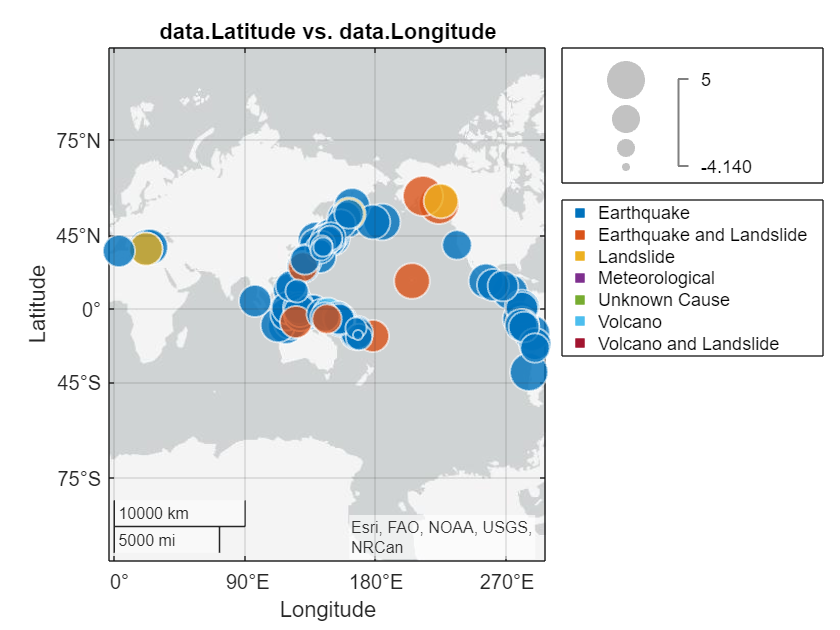

% Create geobubble of selected data
gb = geobubble(data.Latitude,data.Longitude,data.Intensity,data.Cause);

% Add title
title("data.Latitude vs. data.Longitude")

Change the basemap of our visualization.

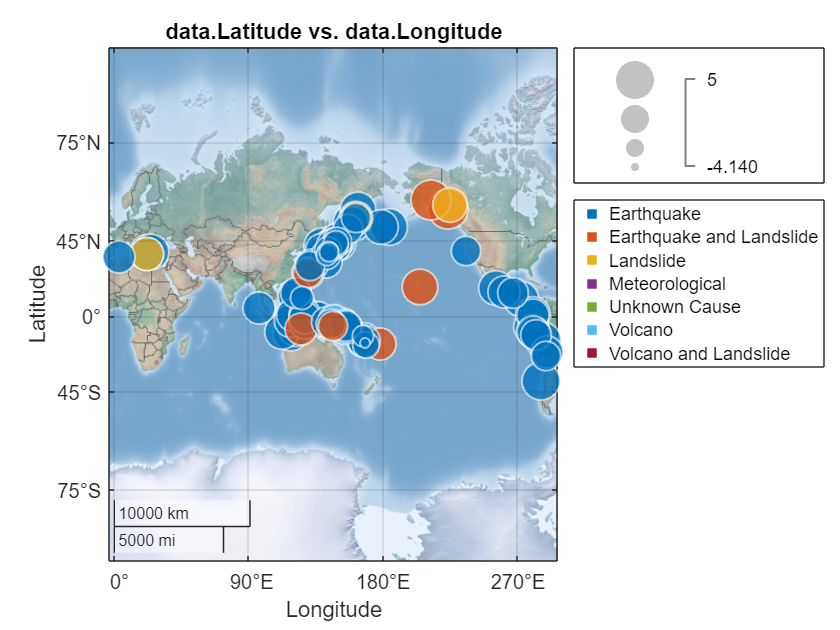

% Create geobubble of selected data
gb = geobubble(data.Latitude,data.Longitude,data.Intensity,data.Cause,"Basemap","colorterrain");

% Add title
title("data.Latitude vs. data.Longitude")

### Visualize data only in INDONESIA and display markers that have a size based on the earthquake magnitude values

Index Table to extract data for Indonesia

dataIndonesia = data(data.Country == 'INDONESIA',:)

dataIndonesia = 14×18 table
    Latitude    Longitude    Year    Month    Day    Hour    Minute    Second    ValidityCode          Validity          CauseCode             Cause              EarthquakeMagnitude     Country            Location           MaxHeight    IidaMagnitude    Intensity
    ________    _________    ____    _____    ___    ____    ______    ______    ____________    ____________________    _________    ________________________    ___________________

Visualize data for Indonesia

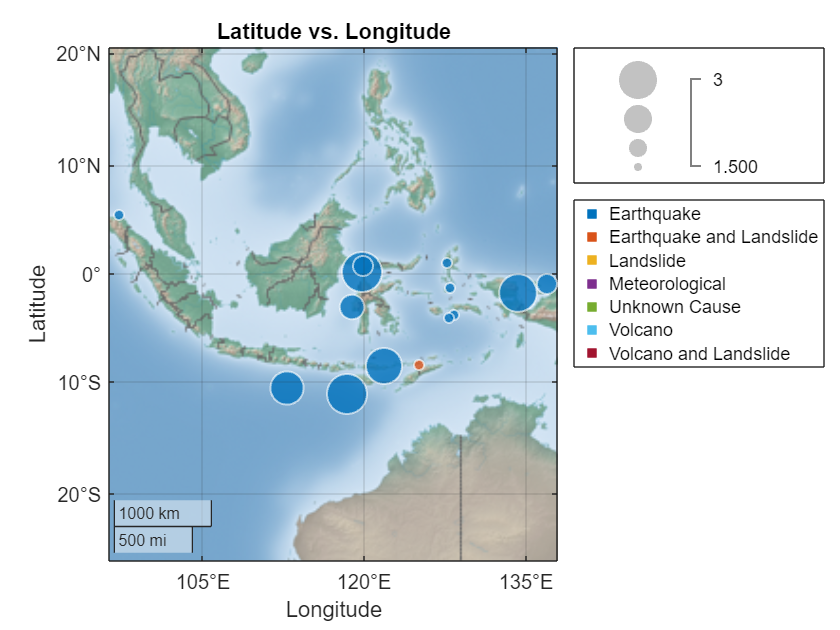

% Create geobubble of selected data
gb = geobubble(dataIndonesia.Latitude,dataIndonesia.Longitude,dataIndonesia.Intensity,dataIndonesia.Cause,"Basemap","colorterrain");

% Add title
title("Latitude vs. Longitude")

### Select only relevant columns

data = data(:,["Intensity" "EarthquakeMagnitude" "IidaMagnitude" "MaxHeight"])

data = 90×4 table
    Intensity    EarthquakeMagnitude    IidaMagnitude    MaxHeight
    _________    ___________________    _____________    _________
       1.5               7.6                 1.5             2.8  
         2               8.1                 2.7             6.5  
         4                 9                 4.2              18  
         1               NaN                 0.5             1.4  
       1.5               6.8                   1               3  
       1.5               7.4                 1.6               3  
         3               5.8                 0.3             1.2  
       3.5               9.1                 3.9           15.24  
       1.5               7.9                 1.3             2.5  
       1.5               7.5                 NaN               1  
         5               8.3              


data = data(data.MaxHeight <= 500 | ismissing(data.MaxHeight),:)

data = 89×4 table
    Intensity    EarthquakeMagnitude    IidaMagnitude    MaxHeight
    _________    ___________________    _____________    _________
       1.5               7.6                 1.5             2.8  
         2               8.1                 2.7             6.5  
         4                 9                 4.2              18  
         1               NaN                 0.5             1.4  
       1.5               6.8                   1               3  
       1.5               7.4                 1.6               3  
         3               5.8                 0.3             1.2  
       3.5               9.1                 3.9           15.24  
       1.5               7.9                 1.3             2.5  
       1.5               7.5                 NaN               1  
       2.5               8.3              

### Develop machine learning model to predict tsunami intensity from Earthquake magnitude, Iida magnitude, and tsunami height

This exploration is inspired by the following article, [https://link.springer.com/article/10.1007/s00024-011-0286-2.](https://link.springer.com/article/10.1007/s00024-011-0286-2.)

regressionLearner

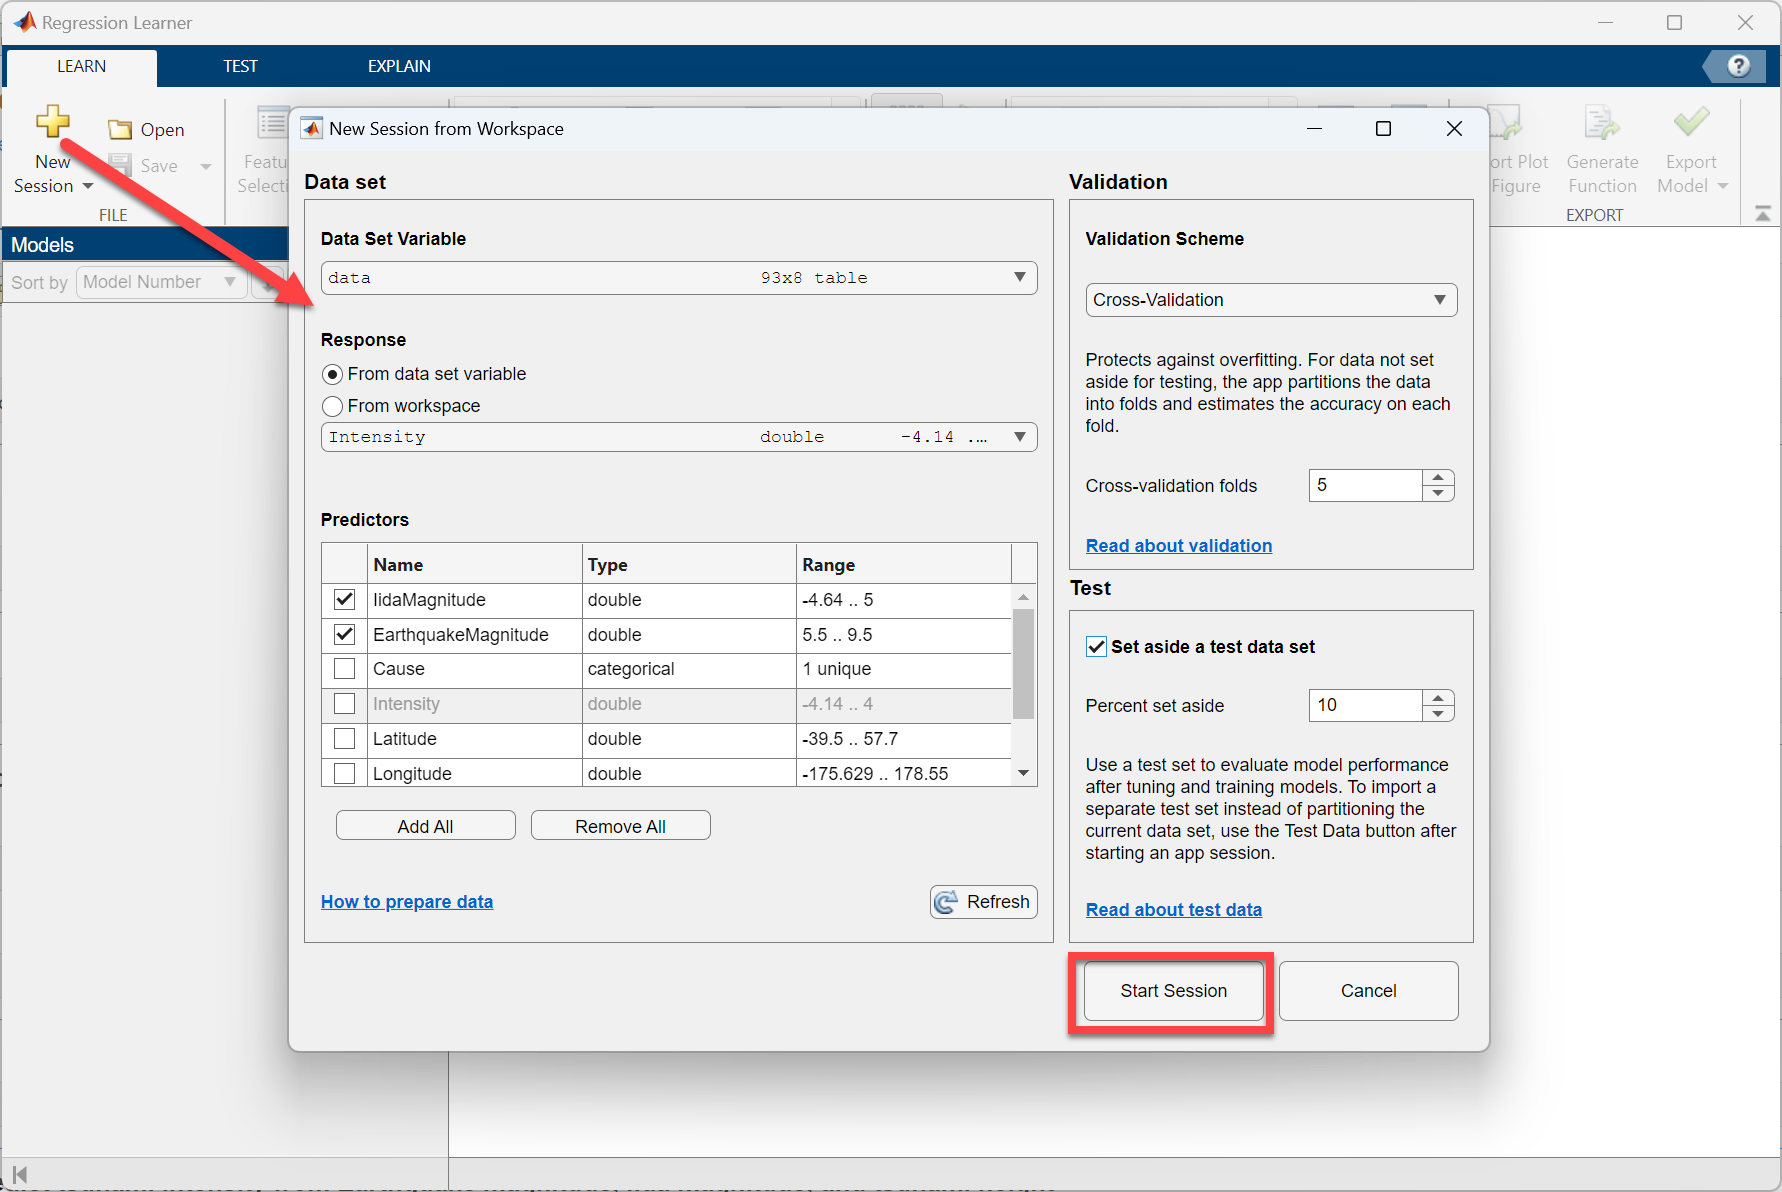

IidaMagnitude = 3

IidaMagnitude = 3

EarthquakeMagnitude = 7

EarthquakeMagnitude = 7

MaxHeight = 20

MaxHeight = 20

predictedIntensity = Model.predictFcn(table(IidaMagnitude,EarthquakeMagnitude,MaxHeight))

predictedIntensity = 2.4360

Model.LinearModel.disp

Linear regression model:
    Intensity ~ 1 + IidaMagnitude + MaxHeight

Estimated Coefficients:
                      Estimate        SE        tStat        pValue  
                     __________    ________    ________    __________
    (Intercept)         0.44674     0.12401      3.6023    0.00059036
    IidaMagnitude       0.68475    0.064586      10.602    3.9642e-16
    MaxHeight        -0.0032485    0.011355    -0.28609       0.77567

Number of observations: 72, Error degrees of freedom: 69
Root Mean Squared Error: 0.676
R-squared: 0.734,  Adjusted R-Squared: 0.727
F-statistic vs. constant model: 95.4, p-value = 1.36e-20


## Create custom prediction app

appdesigner